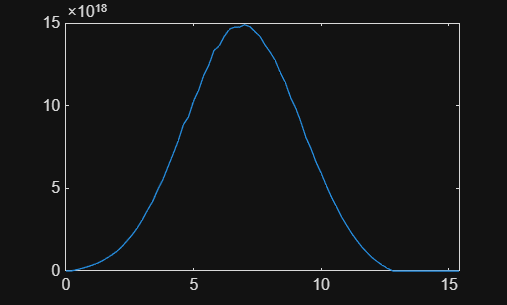

data1 = readmatrix("функция_источника.txt");
data2 = readmatrix('data.txt');
t2 = data2(:, 2);
Mr2  = data2(:, 1);
t1 = data1(:, 1);
Mr1 = data1(:, 2);
plot(t2, Mr2);


time_decimated = t1(1:20:end);
values_decimated = Mr1(1:20:end);
[~, idx1] = max(values_decimated)

idx1 = 32

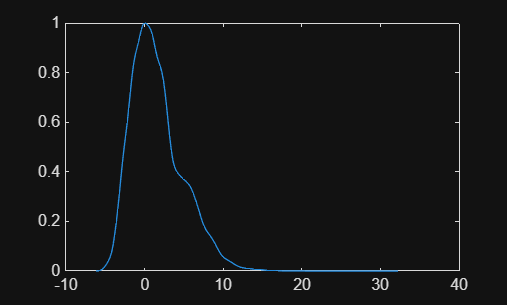

tmax = time_decimated(idx1);
time_shifted = time_decimated - tmax;
plot(time_shifted, values_decimated / max(values_decimated));

[~, idx2] = max(Mr2)

idx2 = 36

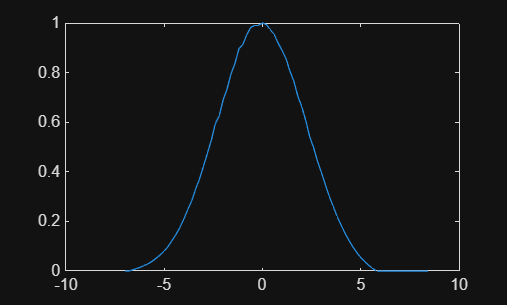

tmax2 = t2(idx2);
time_shifted2 = t2 - tmax2;
plot(time_shifted2, Mr2/max(Mr2));

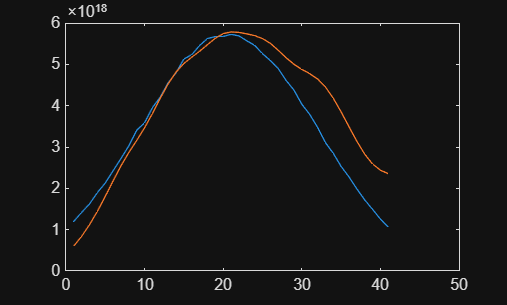

y_exp = values_decimated(idx1 - 20:idx1+20);
y_theor = Mr2(idx2 -20:idx2+20) / 2.6;
y_theor1 = Mr2(idx2 -20:idx2+20);
plot(y_theor);
hold on
plot(y_exp);

mse = sum((y_theor - y_exp).^2) / length(y_theor)

mse = 4.7560e+35

mse1 = sum((y_theor1 - y_exp).^2) / length(y_theor1)

mse1 = 3.7755e+37

error = sum(((y_theor - y_exp) ./ y_theor).^2) / length(y_theor)

error = 0.1350